# Density Estimation

We have seen so far that probability density estimation plays a key role in statistical machine learning.  Let's look at some of the most popular, more flexible ways of doing density estimation.

## Mixture Densities

A **mixture model** is a weighted sum of **component** densities:


$$p(\mathbf x) = \sum_{i-1}^k p(\mathbf x|G_i) P(G_i)$$


where $G_i$ is the $i$th component (aka group or cluster) assumed to be in the data, $P(G_i)$ is the prior/mixture coefficient/weight of the $i$th component and $p(\mathbf x | G_i)$ is the $i$th component pdf. Note that $0 \leq P(G_i) \leq 1, \forall i$ and $\sum_{i=1}^k P(G_i) = 1$.

We will look at Gaussian mixture models (GMMs), so $p(\mathbf x | G_i) = \mathcal{N}(\mathbf{\mu}_i, \Sigma_i)$.

The parameters of our GMM are $\mathbf{\mu}_i, \Sigma_i, P(G_i), i=1,\ldots,k$.  So the LHS of the above equation is more properly written as $p({\mathbf x} | \theta) \equiv p({\mathbf x} | \mathbf{\mu}_i, \Sigma, P(G_i))$

Pics from [Bishop]:

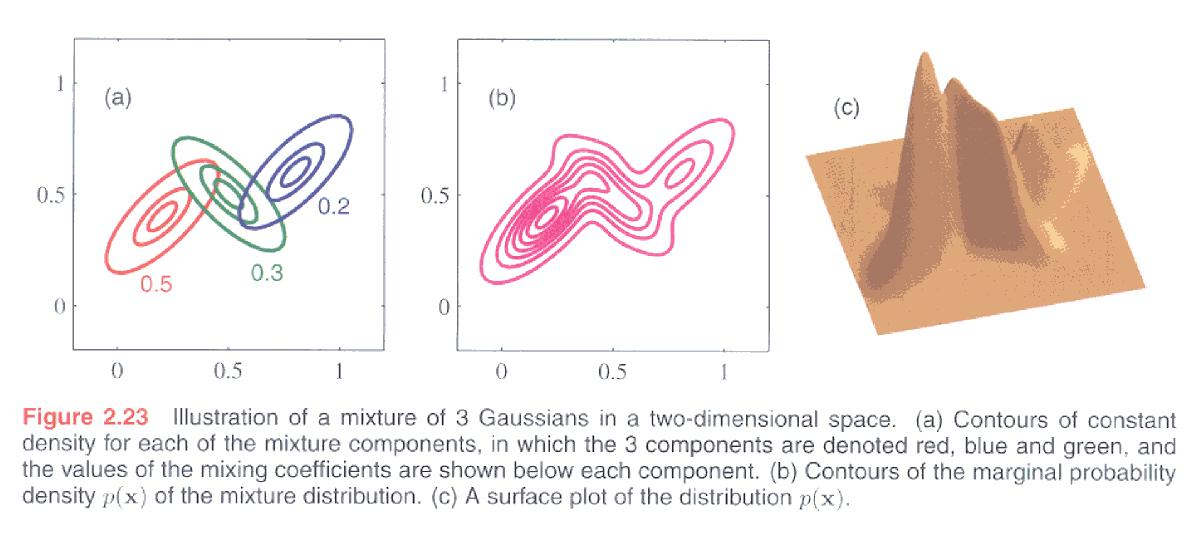

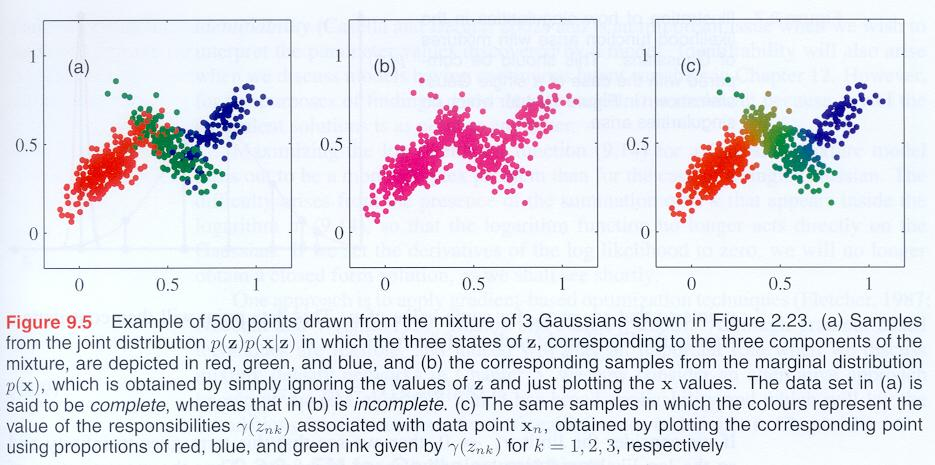

We know how to train a probabilistic model from data - maximize the likelihood:


$$\mathcal{L} = \prod_{j=1}^N p({\mathbf x}_i | \theta)$$


Now, however, there is no closed-form solution.

## The Expectation Maximization (EM) Algorithm

The key issue is that, given some data, we don't know which component Gaussian in the model is "responsible" for it.  Assume that there are hidden or latent "label" variables for this:

$z_i^t = 1$ if $\mathbf{x}^t$ belongs to $G_i$, $0$ otherwise.

The EM algorithm iterates these two steps:

- E step: estimate $z_i^t$ as $h_i^t$ (responsibility value)

- M step: use the $h_i^t$ to update the model parameters (Note: remember [Alpaydin] uses $m$ and $S$ to indicate estimates of $\mu$ and $\Sigma$)

The EM algorithm performs a local optimization of the log-likelihood, following a non-decreasing path and converging.  See [Alpaydin] for the equations.

There is a nice demo at: [http://www.socr.ucla.edu/Applets.dir/MixtureEM.html](http://www.socr.ucla.edu/Applets.dir/MixtureEM.html) . Unfortunately it seems Internet Explorer is the only option to view it!

**Important Practical Issues:**

- Initialization: the model parameters must be given a starting value and the algorithm is sensitive to this initialization of the search.  A common, simple way: choose random data points for each mean; calculate the sample covariance of all the data and use that for each covariance matrix; choose mixture coefficients uniformly.

- Spurious optima: the log-likelihood function may have undesirable optima where one or more variance (or covariance) terms are driven towards zero and the height of the component density approaches $\infty$.

- Choosing $k$ (see why it's called a hyperparameter?): sometimes given by the application.  Otherwise cross-validation could be used, comparing log-likelihood values.  Other approaches also exist.

openExample('stats/FitAGaussianMixtureModelToDataExample')

Another example you can look at:

openExample('stats/ClusteringUsingGaussianMixtureModelsExample')

## Non-Parametric Density Estimation

Generally speaking, non-parametric models impose few strong assumptions about the model, "letting the data speak for itself".

Key ideas:

- Similar inputs have similar outputs

- Functions tend to change smoothly

The $k$-NN classifier is a non-parametic model.  Here we will look at a few non-parametric density estimators (using [Alpaydin]):

- Histograms

- Kernel density estimators

- k-nearest neighbour estimator

Examples from [Bishop]

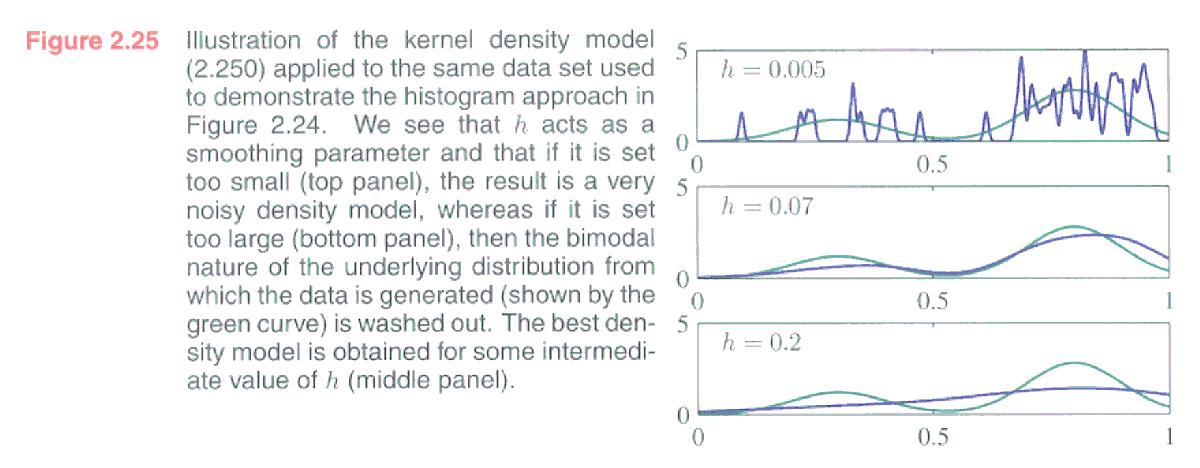

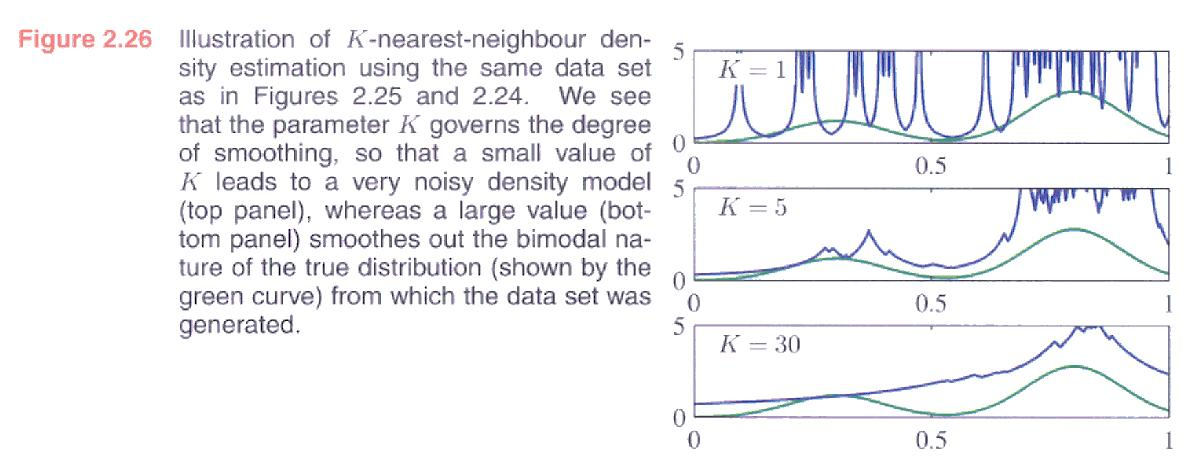

and [HTF]

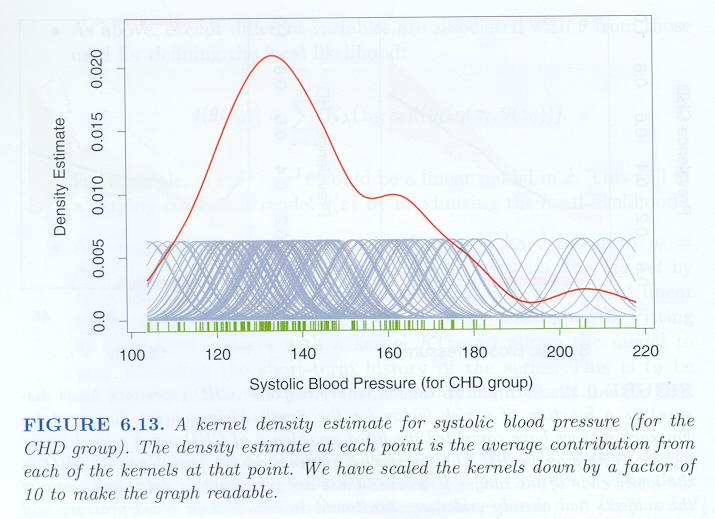

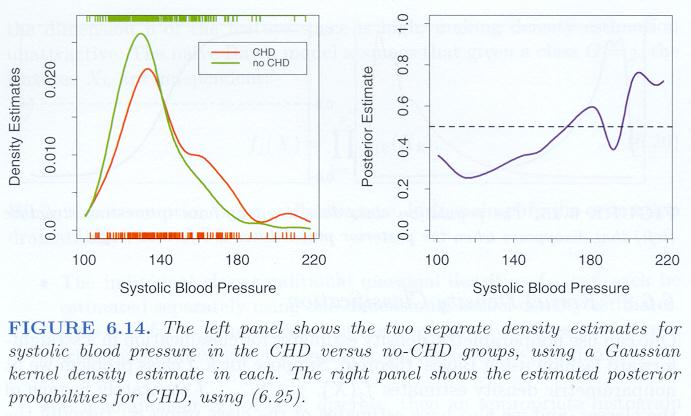

## Computational considerations

For non-parametric estimation, typically storage and prediction are $O(N)$.

For a parametric model (e.g. Gaussian), typically storage $O(d)$ or $O(d^2)$, prediction $O(d)$.

Typically $N > > d$ (but not always!).

## Model Selection considerations

We have to choose the value of $k$ or $h$ in these models:

- If $k$ or $h$ is small, a single data point matters a lot, leading to low bias but high variance.

- If $k$ or $h$ is large, the model averages/smoothes over many data points, leading to a high bias but low variance.

## Multivariate Non-Parametric models

The techniques above extend fairly easily to higher dimensions.  But it is worth being at least cautious if you plan on doing density estimation in a high-dimensional space.  You might be hit with the [Curse of Dimensionality](https://en.wikipedia.org/wiki/Curse_of_dimensionality)!